## Backtesting a set of tickers 

The objective of this notebook is to showcase how to backtest a portfolio consisting of a number of tickers and weights.

### Importing market data

Duplicate table variable name: 'Date'.

initDate = '1-Jan-2014';
symbol = 'AAPL';
aaplusd_yahoo_raw = getMarketDataViaYahoo(symbol, initDate);
aaplusd_yahoo = timeseries([aaplusd_yahoo_raw.Close, aaplusd_yahoo_raw.High, aaplusd_yahoo_raw.Low], datestr(aaplusd_yahoo_raw(:,1).Date));
aaplusd_yahoo.DataInfo.Units = 'USD';
aaplusd_yahoo.Name = symbol;
aaplusd_yahoo.TimeInfo.Format = "dd-mm-yyyy";
aaplusd_yahoo.plot()

### Construct and backtest a portfolio

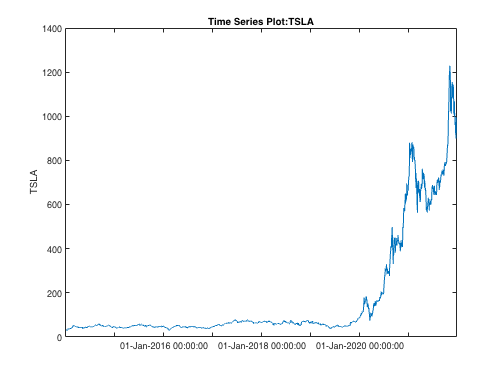

weight_apple = 0.5;
weight_tesla = 0.5;

history = getMarketDataViaYahoo('TSLA', initDate);
apple = getMarketDataViaYahoo('AAPL', initDate);

tsla_price = timeseries(history.Close, datestr(history(:,1).Date), 'Name', "TSLA");
apple_price = timeseries(apple.Close, datestr(apple(:,1).Date), 'Name', "AAPL");
tsla_price.plot()

TT = timeseries2timetable([tsla_price apple_price])

TT = 2009×2 timetable
       Time         TSLA      AAPL 
    ___________    ______    ______

    02-Jan-2014     30.02    19.755
    03-Jan-2014    29.912    19.321
    06-Jan-2014      29.4    19.426
    07-Jan-2014    29.872    19.287
    08-Jan-2014    30.256    19.409
    09-Jan-2014    29.506    19.161
    10-Jan-2014    29.144    19.034
    13-Jan-2014    27.868    19.133
    14-Jan-2014    32.254    19.514
    15-Jan-2014    32.826    19.906
    16-Jan-2014    34.194    19.795
    17-Jan-2014    34.002     19.31
    21-Jan-2014    35.336     19.61
    22-Jan-2014    35.712    19.697
    23-Jan-2014      36.3    19.864
    

TT.TSLA

ans = 	1.0e+03 *

    0.0300
    0.0299
    0.0294
    0.0299
    0.0303
    0.0295
    0.0291
    0.0279
    0.0323
    0.0328


## Dynamically read tickers from text file

fileID = fopen('tickers.txt','r');
initDate = '1-Jan-2014';
A = fscanf(fileID, "%s");
tickers = strsplit(A, ",");
results = {};
for tckr = tickers
    history = getMarketDataViaYahoo(tckr{1}, initDate);    
    history_price = timeseries(history.Close, datestr(history(:,1).Date), 'Name', tckr{1});
    results = [results history_price];
end
tt = timeseries2timetable(results);

tt = 2010×2 timetable
       Time         TSLA      AAPL 
    ___________    ______    ______

    02-Jan-2014     30.02    19.755
    03-Jan-2014    29.912    19.321
    06-Jan-2014      29.4    19.426
    07-Jan-2014    29.872    19.287
    08-Jan-2014    30.256    19.409
    09-Jan-2014    29.506    19.161
    10-Jan-2014    29.144    19.034
    13-Jan-2014    27.868    19.133
    14-Jan-2014    32.254    19.514
    15-Jan-2014    32.826    19.906
    16-Jan-2014    34.194    19.795
    17-Jan-2014    34.002     19.31
    21-Jan-2014    35.336     19.61
    22-Jan-2014    35.712    19.697
    23-Jan-2014      36.3    19.864
    

writetimetable(tt, "market_data.csv")